clc
close all
clear

syms d real
syms z real

b = 0.6*d + 0.2*d^2;
a = 1 + 0.2*d + 0.01*d^2;
delta = 1;
[qrmin,pr]=axminbyc(b,a,delta,d)

$$qrmin = \frac{17\,d}{980}+\frac{12}{49}$$

$$pr = 1-\frac{17\,d}{49}$$

negative power of z 

Fw = 

S = b/a;
R = qrmin/pr;
Fw = simplify(R*S/(1+R*S))

$$Fw = \frac{d\,\left(17\,d^{2}+291\,d+720\right)}{4900}$$


Fw = simplify(subs(Fw,d,z^(-1)))

$$Fw = \frac{720\,z^{2}+291\,z+17}{4900\,z^{3}}$$


[num,den] = numden(Fw)

$$num = 720\,z^{2}+291\,z+17$$

$$den = 4900\,z^{3}$$

numcoefs = double(fliplr(coeffs(num)))

numcoefs =    720   291    17


dencoefs = double(fliplr(coeffs(den)))

dencoefs = 4900

Fwtf = tf(numcoefs,[dencoefs, 0, 0, 0], 1)

Fwtf =
 
  720 z^2 + 291 z + 17
  --------------------
        4900 z^3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


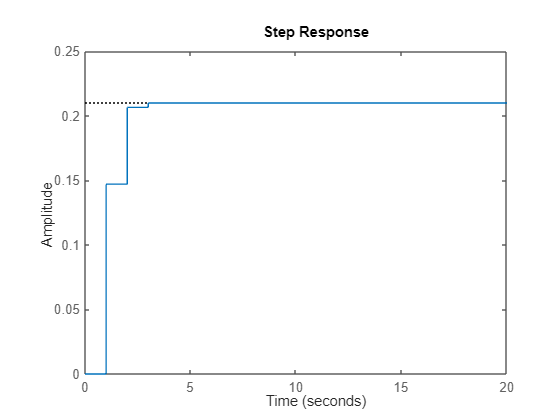

step(Fwtf)